**1. Stability** (25 marks)

a) (5 marks) Is the open loop plant


$$G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}$$


stable or unstable.

syms s
RT=[s^4 1 182 600;s^3 23 580 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 600\\ s^{3} & 23 & 580 & 0 \end{array}\right)$$

RT=[RT;s^2 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,2) -det([RT(1,2) RT(1,4);RT(2,2) RT(2,4)])/RT(2,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 600\\ s^{3} & 23 & 580 & 0\\ s^{2} & \frac{3606}{23} & 600 & 0 \end{array}\right)$$

RT=[RT;s^1 -det([RT(2,2) RT(2,3);RT(3,2) RT(3,3)])/RT(3,2) -det([RT(2,2) RT(2,4);RT(3,2) RT(3,4)])/RT(3,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 600\\ s^{3} & 23 & 580 & 0\\ s^{2} & \frac{3606}{23} & 600 & 0\\ s & \frac{295680}{601} & 0 & 0 \end{array}\right)$$

RT=[RT;s^0 -det([RT(3,2) RT(3,3);RT(4,2) RT(4,3)])/RT(4,2) -det([RT(3,2) RT(3,4);RT(4,2) RT(4,4)])/RT(4,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 600\\ s^{3} & 23 & 580 & 0\\ s^{2} & \frac{3606}{23} & 600 & 0\\ s & \frac{295680}{601} & 0 & 0\\ 1 & 600 & 0 & 0 \end{array}\right)$$

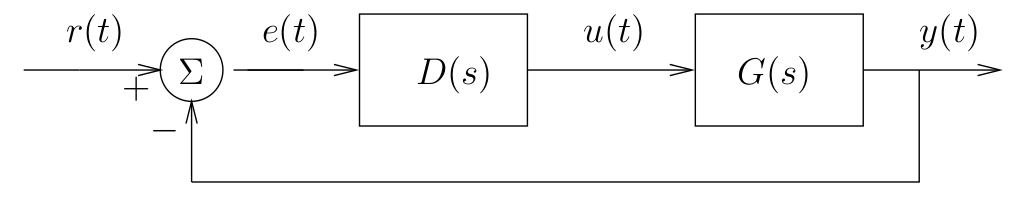

Consider the system shown above where:


$$D(s)=K\;\mbox{ and } \;G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}$$


b) (5 marks) Compute the closed loop transfer function of the system

syms sigma s K 
G=zpk([-3],[-2 -5 -6 -10],1)


G =
 
           (s+3)
  ------------------------
  (s+2) (s+5) (s+6) (s+10)
 
Continuous-time zero/pole/gain model.



[num,den]=tfdata(G)

num = 1×1 cell array
    {1×5 double}


den = 1×1 cell array
    {1×5 double}


Gs=poly2sym(cell2mat(num),s)/poly2sym(cell2mat(den),s)

$$Gs = \frac{s+3}{s^{4}+23\,s^{3}+182\,s^{2}+580\,s+600}$$

Gcls=K*Gs/(1+K*Gs)

$$Gcls = \frac{K\,\left(s+3\right)}{\left(\frac{K\,\left(s+3\right)}{s^{4}+23\,s^{3}+182\,s^{2}+580\,s+600}+1\right)\,\left(s^{4}+23\,s^{3}+182\,s^{2}+580\,s+600\right)}$$

c) (10 marks) For what values of K is the closed loop system stable?

Gcls=collect(simplifyFraction(Gcls))

$$Gcls = \frac{K\,s+3\,K}{s^{4}+23\,s^{3}+182\,s^{2}+\left(K+580\right)\,s+3\,K+600}$$

RT=[s^4 1 182 3*K+600;s^3 23 K+580 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0 \end{array}\right)$$

RT=[RT;s^2 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,2) -det([RT(1,2) RT(1,4);RT(2,2) RT(2,4)])/RT(2,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0\\ s^{2} & \frac{3606}{23}-\frac{K}{23} & 3\,K+600 & 0 \end{array}\right)$$

Multypliy $s^2$ row by 23.

RT(3,2)=23*RT(3,2)

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0\\ s^{2} & 3606-K & 3\,K+600 & 0 \end{array}\right)$$

RT(3,3)=23*RT(3,3)

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0\\ s^{2} & 3606-K & 69\,K+13800 & 0 \end{array}\right)$$

Now continue.

RT=[RT;s^1 -det([RT(2,2) RT(2,3);RT(3,2) RT(3,3)])/RT(3,2) -det([RT(2,2) RT(2,4);RT(3,2) RT(3,4)])/RT(3,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0\\ s^{2} & 3606-K & 69\,K+13800 & 0\\ s & -\frac{-K^{2}+1439\,K+1774080}{K-3606} & 0 & 0 \end{array}\right)$$

RT=[RT;s^0 -det([RT(3,2) RT(3,3);RT(4,2) RT(4,3)])/RT(4,2) -det([RT(3,2) RT(3,4);RT(4,2) RT(4,4)])/RT(4,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0\\ s^{2} & 3606-K & 69\,K+13800 & 0\\ s & -\frac{-K^{2}+1439\,K+1774080}{K-3606} & 0 & 0\\ 1 & 69\,K+13800 & 0 & 0 \end{array}\right)$$

RT(4,2)=simplifyFraction(RT(4,2))

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0\\ s^{2} & 3606-K & 69\,K+13800 & 0\\ s & -\frac{-K^{2}+1439\,K+1774080}{K-3606} & 0 & 0\\ 1 & 69\,K+13800 & 0 & 0 \end{array}\right)$$

maybeK=roots([-1 1439 1774080])

maybeK =    1.0e+03 *

    2.2334
   -0.7944


d) (5 marks) Calculate the $j\omega$-axis crossings (frequency). From your answer to (1c) you know the value of $K$ where this occurs.

Two possible solutions:

Solution 1:

Take the solution of the polynomial corresponding to the $s^2$row of the Routh table.

roots([3606-maybeK(1) 0 69*maybeK(1)+13800])

ans =    0.0000 +11.0598i
   0.0000 -11.0598i


**2. Root Locus, Time Response and Controller Design** (25 marks)

Consider Fig. 1 in the case when:


$$D(s)=K\;\mbox{ and }\; G(s)=\frac{s+3}{(s+2)(s+5)(s+6)(s+10)}$$


s=tf('s')


s =
 
  s
 
Continuous-time transfer function.



G=(s+3)/((s+2)*(s+5)*(s+6)*(s+10))


G =
 
                 s + 3
  ------------------------------------
  s^4 + 23 s^3 + 182 s^2 + 580 s + 600
 
Continuous-time transfer function.



a) (5 marks) Sketch the root locus for the control system. You do not need to calculate the exact breakaway/breakin points.

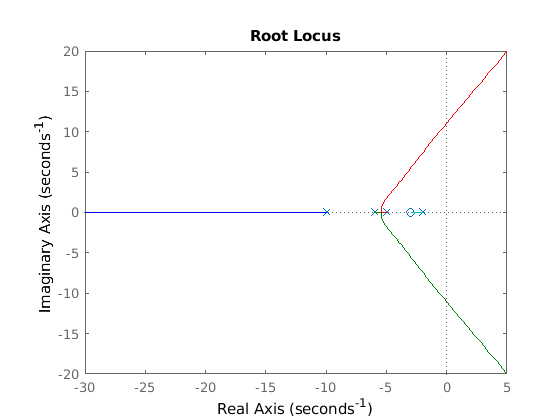

rlocus(G)

b) (5 marks) For K = 430 the system is stable and the closed loop poles are approximately

located at

s = −2.7 ± j6.1, −2.9, −14.7

Assuming that the closed loop pole at s = −2.9 cancels the system zero at s = −3, what

is the damping ratio of the dominant poles? Assuming ideal 2nd order behaviour, what

do you expect the resulting percent overshoot to be for the system?

K=430

K = 430

Gcl=feedback(K*G,1)


Gcl =
 
               430 s + 1290
  --------------------------------------
  s^4 + 23 s^3 + 182 s^2 + 1010 s + 1890
 
Continuous-time transfer function.



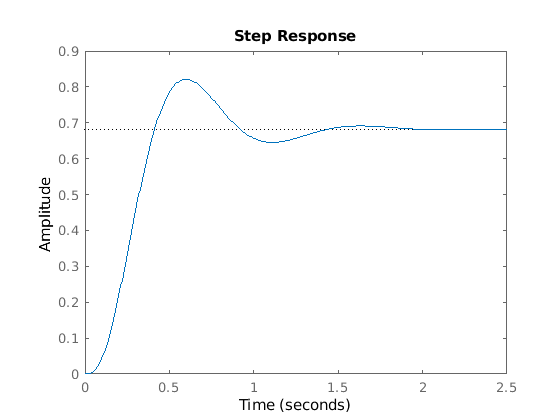

step(Gcl)

p=pole(Gcl)

p =  -14.6971 + 0.0000i
  -2.6999 + 6.0832i
  -2.6999 - 6.0832i
  -2.9032 + 0.0000i


zeta=cos(pi-angle(p(2)))

zeta = 0.4057

pos=exp(-zeta*pi/sqrt(1-zeta^2))*100

pos = 24.8006

c) (5 marks) Your manager said that she is happy with % overshoot of your controller design for K = 430, but she would like you to design a PD compensator to cut the settling time in half while keeping the same % overshoot. Assuming ideal 2nd order behaviour, what would be the new location for the dominant poles?

finalValue=evalfr(Gcl,0)

finalValue = 0.6825

peakValue=max(step(Gcl))

peakValue = 0.8211

actualPOS=(peakValue-finalValue)/finalValue*100

actualPOS = 20.3018

(0.8211-.6825)/0.6825

ans = 0.2031

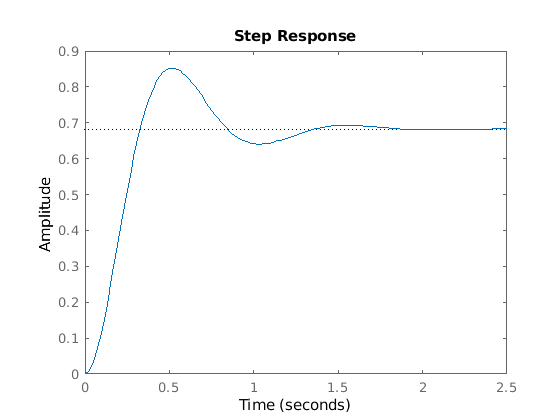

step(1290/1890*p(2)*p(3)/((s-p(2))*(s-p(3))))


s_d=2*p(2)

s_d =   -5.3997 +12.1664i


theta=angle(evalfr(G,-5.4+j*12.2))

theta = 1.8702

zc=12.2/tan(pi-theta)+5.4

zc = 9.1656



rlocus(G)
hold

Current plot held


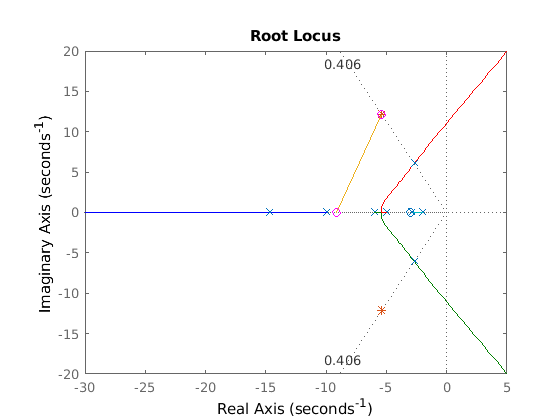

Current plot released


plot(p,'x')
plot([2*p(2) 2*p(3)],'*')
sgrid(zeta,0)
plot([-zc+j*0 2*p(2)])
plot([-zc+j*0 2*p(2)],'mo')
hold


D=s+zc


D =
 
  s + 9.166
 
Continuous-time transfer function.



angle(evalfr((s+zc)*G,-5.4+j*12.2))*180/pi

ans = 180

newpole=2*p(2)

newpole =   -5.3997 +12.1664i




Gclnew=feedback(K*D*G,1)


Gclnew =
 
         430 s^2 + 5231 s + 1.182e04
  ------------------------------------------
  s^4 + 23 s^3 + 612 s^2 + 5811 s + 1.242e04
 
Continuous-time transfer function.



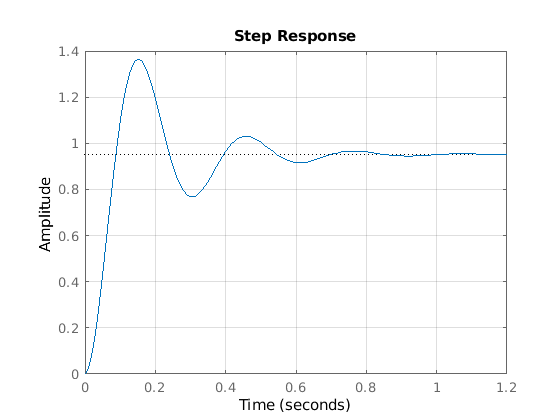

step(Gclnew)
grid

max(step(Gclnew))

ans = 1.3648

**3. Steady State Error** (15 marks)

Assume that


$$G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}=\frac{s+3}{(s+2)(s+5)(s+6)(s+10)}$$


in Fig. 1/

a) (5 marks) Assuming the feedback configuration shown in Fig. 1 and $D(s) = K$ is chosen so that the closed loop system is stable, what is the type of the system? What is its static error constant for a given gain $K$? What is the steady state error of the closed loop systemin response to a unit step input?

syms s K
Gs=(s+3)/(s^4+23*s^3+182*s^2+580*s+600)

$$Gs = \frac{s+3}{s^{4}+23\,s^{3}+182\,s^{2}+580\,s+600}$$

K_p=subs(K*Gs,s,0)

$$K\_p = \frac{K}{200}$$

For $K=430$ we have:

K_p_430=subs(K_p,K,430)

$$K\_p\_430 = \frac{43}{20}$$

or doing it numerically we would have:

K=430

K = 430

K_p_430=evalfr(K*G,0)

K_p_430 = 2.1500

e_step=1/(1+K_p)

$$e\_step = \frac{1}{\frac{K}{200}+1}$$

e_step_430=1/(1+K_p_430)

e_step_430 = 0.3175

b) (5 marks) The system requires the elimination of the steady state error and robustness

with respect to step disturbances. You colleague (who graduated from McMaster) suggests changing the controller from $D(s) = K$ to an integral controller $D(s) = \frac{K}{s}$. Is this a good choice? Does it eliminate the steady state error and still have the same % overshoot for an appropriate choice of K? What might have changed? Justify your answer.

s=tf('s')


s =
 
  s
 
Continuous-time transfer function.



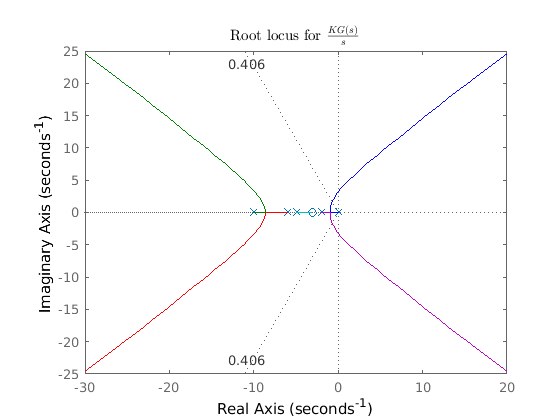

rlocus(G/s)
sgrid(zeta,0)
title('Root locus for $\frac{KG(s)}{s}$','Interpreter','latex' )

**4. State Space Control** (20 marks)

Assume that the plant is given by:


$$G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}$$


a) (5 marks) Given G(s) what is the controller canonical (phase variable) state space representation of the plant G(s)?

A=[0 1 0 0;0 0 1 0;0 0 0 1 ;-600 -580 -182 -23]

A =      0     1     0     0
     0     0     1     0
     0     0     0     1
  -600  -580  -182   -23


B=[0 0 0 1]'

B =      0
     0
     0
     1


C=[3 1 0 0]

C =      3     1     0     0


[n,d]=ss2tf(A,B,C,0)

n =      0     0     0     1     3


d =     1.0000   23.0000  182.0000  580.0000  600.0000


G_stateSpace=tf(n,d)


G_stateSpace =
 
                 s + 3
  ------------------------------------
  s^4 + 23 s^3 + 182 s^2 + 580 s + 600
 
Continuous-time transfer function.



b) (5 marks) A state feedback control $u = -Kx$ is to be used to:

• place one of the closed loop poles is to be placed at $s = -3$ to exactly cancel the system zero,

• place the dominant poles at $s = -5.4 \pm j12.2$ to get the desired % overshoot and settling time, and

• place the final pole at $s = -54$ so it won’t interfere.

What would the desired characteristic equation of the designed closed loop system be?

(s+5.4+j*12.2)*(s+5.4-j*12.2)*(s+3)*(s+54)


ans =
 
  s^4 + 67.8 s^3 + 955.6 s^2 + 1.19e04 s + 2.884e04
 
Continuous-time transfer function.



**5. Bode Plot Margins, Bandwidth & Digital Control** (15 marks)

The open loop bode plot of D(s)G(s) for:


$$D(s)=K=430, G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}$$


a) (5 marks) What is the gain margin for the system? What is the phase margin? How much could the gain change by before the systems would be unstable? (Note your answer to (1c) might help with this question.)

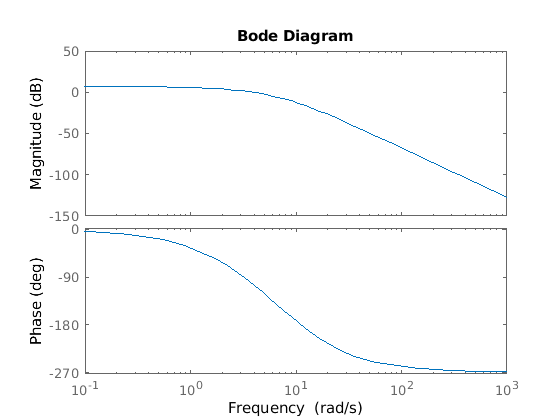

bode(K*G)

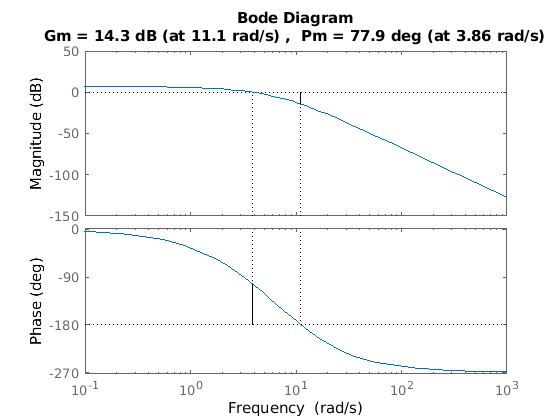

margin(K*G)

[M,phi]=margin(K*G)

M = 5.1947

phi = 77.9352

20*log10(M)

ans = 14.3111

2233.4/430

ans = 5.1940

b) (5 marks) The Bode plot for the closed loop system with D(s) = K = 430 is shown below.

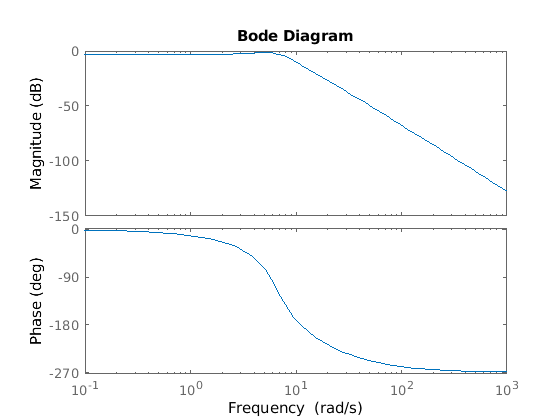

bode(Gcl)

omega_BW=bandwidth(Gcl)

omega_BW = 8.4235

c) (5 marks) What is the formula to compute the Zero Order Hold Equivalent of the plant $G(s)$? For a sampling rate of 10 Hz, where would the pole corresponding to $s = -6$ be located in the z-plane? (Note: You do not have to solve for the complete Zero Order Hold equivalent of $G(s)$, just give the general formula and compute the z-plane pole location for $s = -6$).

T=1/10

T = 0.1000

exp(-6*T)

ans = 0.5488

Gzoh=c2d(G,T,'zoh')
pole(zoh)